**Development of HR models and parameter estimation**

Based on simulated data with artificial resp. real-world power measurements

clear; close all; clc;

% Extracting data for a specific activity
athleticData = import_data();
activityId = 8752058834;
N = 3600;
testData = getTestData(athleticData, activityId, N);

% Storage
power = zeros(N, 1);        % power(k) = constant power in the k-th second
hr = zeros(N, 1);           % hr(k) = HR at end of the k-th second
hr_prime = zeros(N, 1);     % hr_prime(k) = (left-sided) derivative of HR at the end of k-th second

Lists of solvers and methods for estimation of derivative

solver_list = ["least-squares", "fmincon"];
derivative_list = ["ode", "finite_diff", "Savitzky_Golay"];

Selection/definitions of power demand and  heart rate

% POWER FROM STEP PROTOCOL OR STRAVA MEASUREMENT?

% power demand as step protocol (30 W increase every 180 sec)
% for t = 1:N
%     power(t) = 100 + (30 * floor((t-1)/180));   % 180 seconds of 100W, 130W, ...
% end

% power demand from sample of Strava data
power = table2array(testData(:,"power"));

% SIMULATED OR STRAVA MEASURED HEART RATE?

% heart rate for the power demand by the model
% ground truth model parameters
tau_true = 24.0;
hr0_true = 75.0;
rest_true = 55.0;
gain_true = 0.2;
hr = ode_solve (power, hr0_true, tau_true, rest_true, gain_true);

% heart rate from sample of Strava data
hr = table2array(testData(:,"heartrate"));

% Test Savitzky-Golay 

# Savitzky-Golay Differentiation

Generate the heart rate signal sampled one times a second for 3600 seconds.

x = hr;

Smooth the data and estimate the first derivative using the Savitzky-Golay method. Use 25 (9)-sample frames and fifth (third) order polynomials.

[b,g] = sgolay(3,9);
dx = zeros(length(x),2);
for p = 0:1
  dx(:,p+1) = conv(x, factorial(p)/(-1)^p * g(:,p+1), 'same');
end

Plot the original signal, the smoothed sequence, and the derivative estimates.

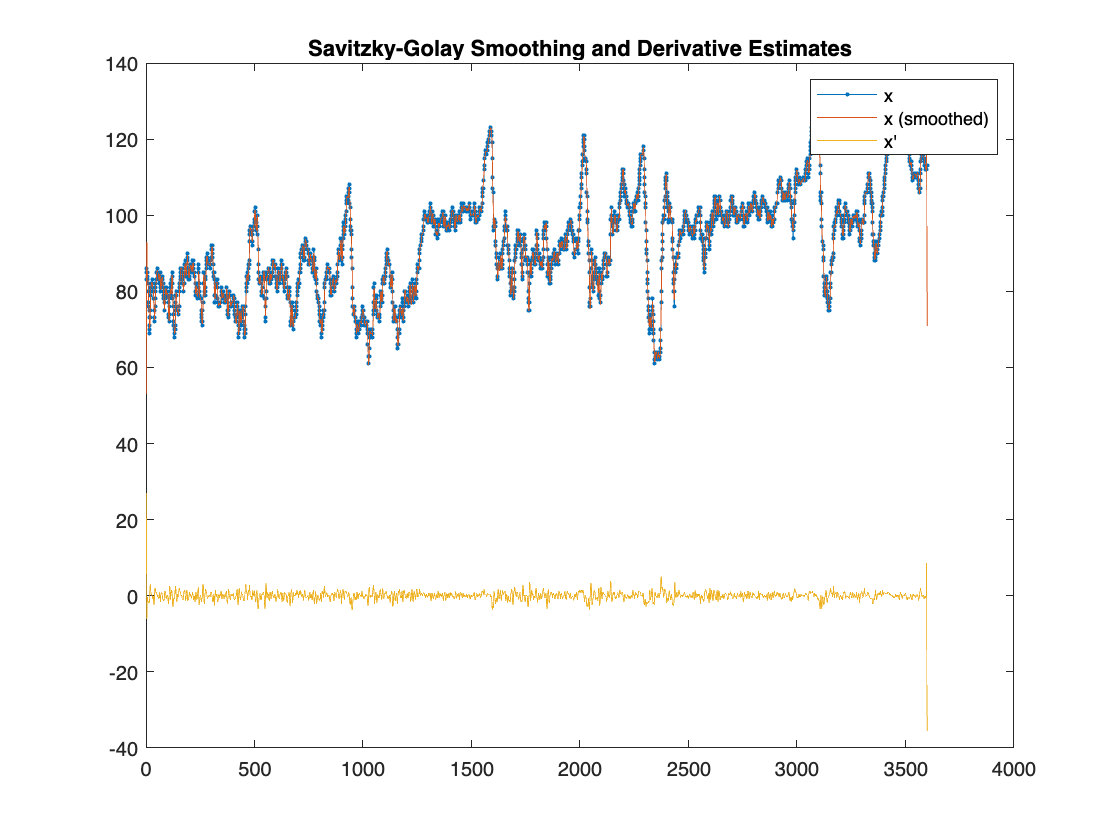

plot(x,'.-')
hold on
plot(dx)
hold off
legend('x','x (smoothed)','x''')
title('Savitzky-Golay Smoothing and Derivative Estimates')

For each method of derivative computation

- solve the system using least squares

- run the model on the solution

- validate the RMSE

lsqr converged at iteration 4 to a solution with relative residual 1.7e-16.




Derivative estimation by             ode


            ode derivative: tau: 24.000000 rest: 55.000000 gain:  0.200000   RMSE 12.344110


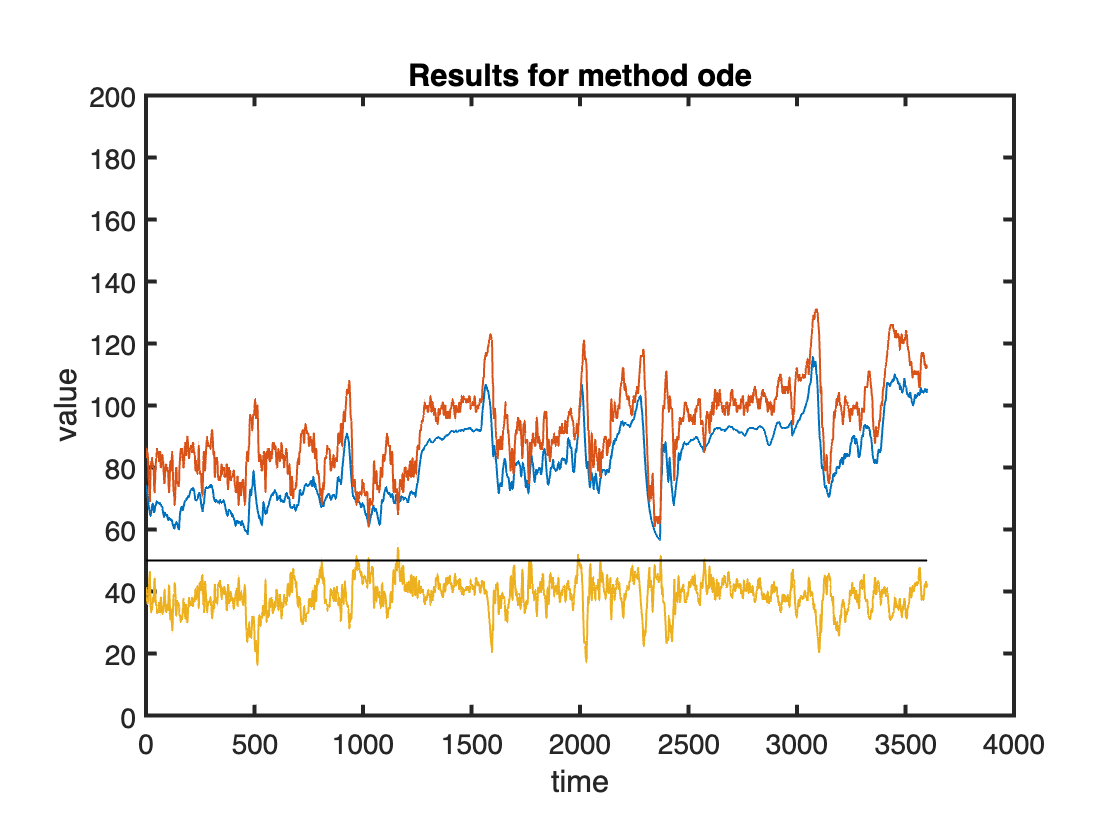

lsqr converged at iteration 3 to a solution with relative residual 0.11.




Derivative estimation by     finite_diff


    finite_diff derivative: tau:  0.973473 rest: 79.578205 gain:  0.099548   RMSE 10.230552


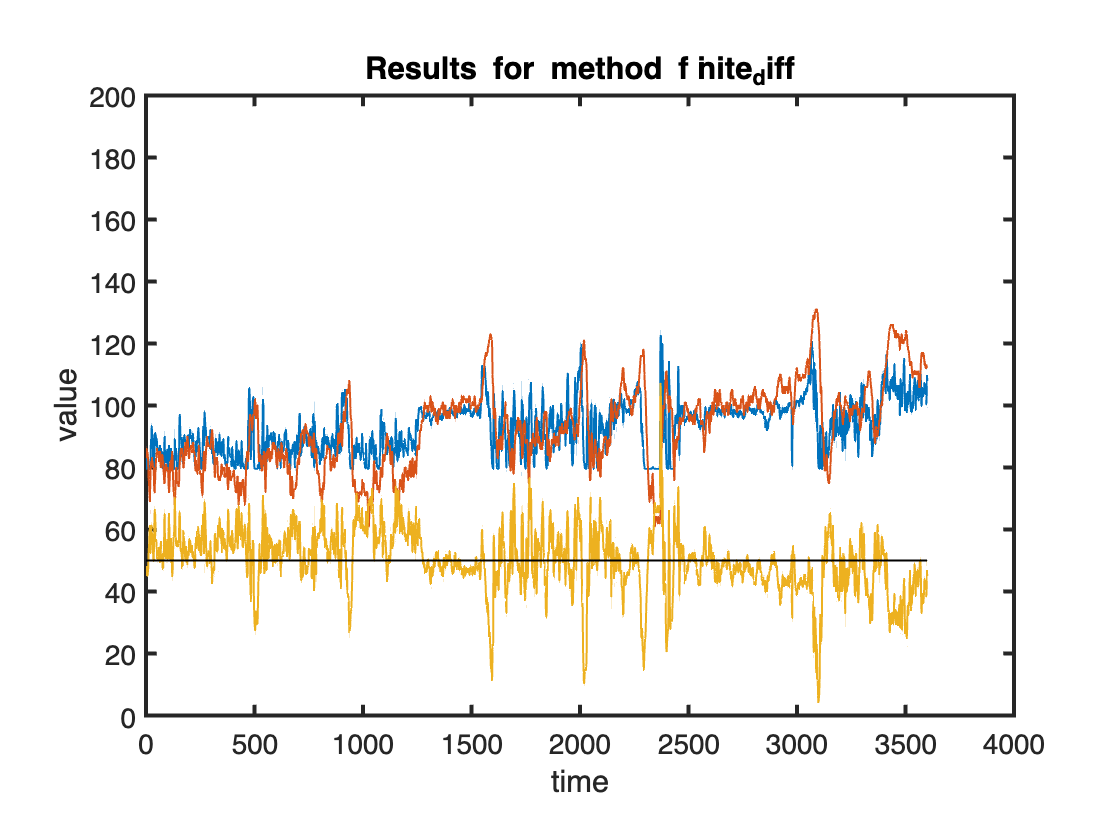

lsqr converged at iteration 3 to a solution with relative residual 0.11.




Derivative estimation by  Savitzky_Golay


 Savitzky_Golay derivative: tau:  1.353300 rest: 79.468408 gain:  0.100340   RMSE 10.041229


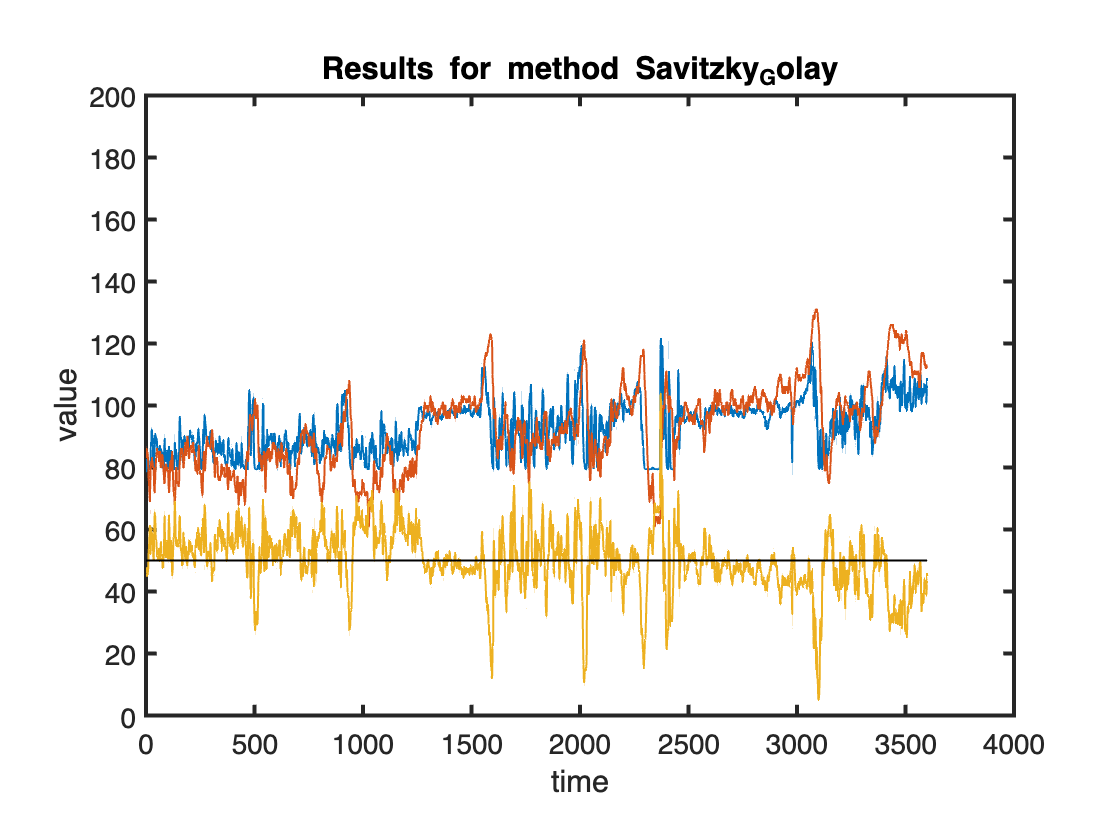

for derivative = derivative_list
    switch derivative
        case 'ode'             % ODE (ground truth derivative)
            hr_prime = (equilibrium(power, rest_true, gain_true) - hr) / tau_true;
        case 'finite_diff'     % backward finite differences
            hr_prime = diff([2*hr(1)-hr(2); hr]);        % 2*hr(1)-hr(2)
        case 'Savitzky_Golay'  % Savitzky_Golay filter, order ?
            hr_prime = sgdiff(hr, 3, 9);
    end
    [tau, rest, gain] = ls_solve (hr, hr_prime, power);
    hr_model = ode_solve (power, hr0_true, tau, rest, gain);    % no hr0 from ls_solve
    RMSE = rmse(hr_model,hr);
    fprintf("\n\nDerivative estimation by %15s\n", derivative{1});
    fprintf("%15s derivative: tau:%10.6f rest:%10.6f gain:%10.6f   RMSE %9.6f\n", ...
        derivative{1}, tau, rest, gain, RMSE);
    show_your_work(hr_model, hr, power, derivative);
end

Run also the fmincon optimization

[tau, hr0, rest, gain] = ip_solve (hr, power);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    5.394605e+00    0.000e+00    1.983e+00
    1      18    5.320501e+00    0.000e+00    1.414e+01    1.066e-02
    2      23    5.283820e+00    0.000e+00    1.385e-01    1.032e-01
    3      28    5.272002e+00    0.000e+00    2.667e+00    1.352e-01
    4      33    5.210183e+00    0.000e+00    8.298e+00    8.906e-01
    5      38    5.154887e+00    0.000e+00    8.149e+00    1.477e+00
    6      43    5.145770e+00    0.000e+00    3.202e+00    3.150e-01
    7      48    5.144054e+00    0.000e+00    1.353e-01    2.204e-02
    8      53    5.143927e+00    0.000e+00    1.511e-01    1.927e-02
    9      58    5.143474e+00    0.000e+00    8.759e-01    7.428e-02
   10      63    5.142652e+00    0.000e+00    1.724e+00    1.492e-01
   11      68    5.140708e+00    0.000e+00    2.918e+00    3.983e-01
   12      73    5.137313e+00    0.000e+00    3

hr_model = ode_solve (power, hr0, tau, rest, gain);
fprintf("fmincon: tau: %10.6f hr0: %10.6f rest: %10.6f gain: %10.6f   RMSE %9.6f\n", ...
    tau, hr0, rest, gain, rmse(hr_model,hr));

fmincon: tau:  24.436131 hr0:  87.380858 rest:  66.483448 gain:   0.198159   RMSE  5.097039


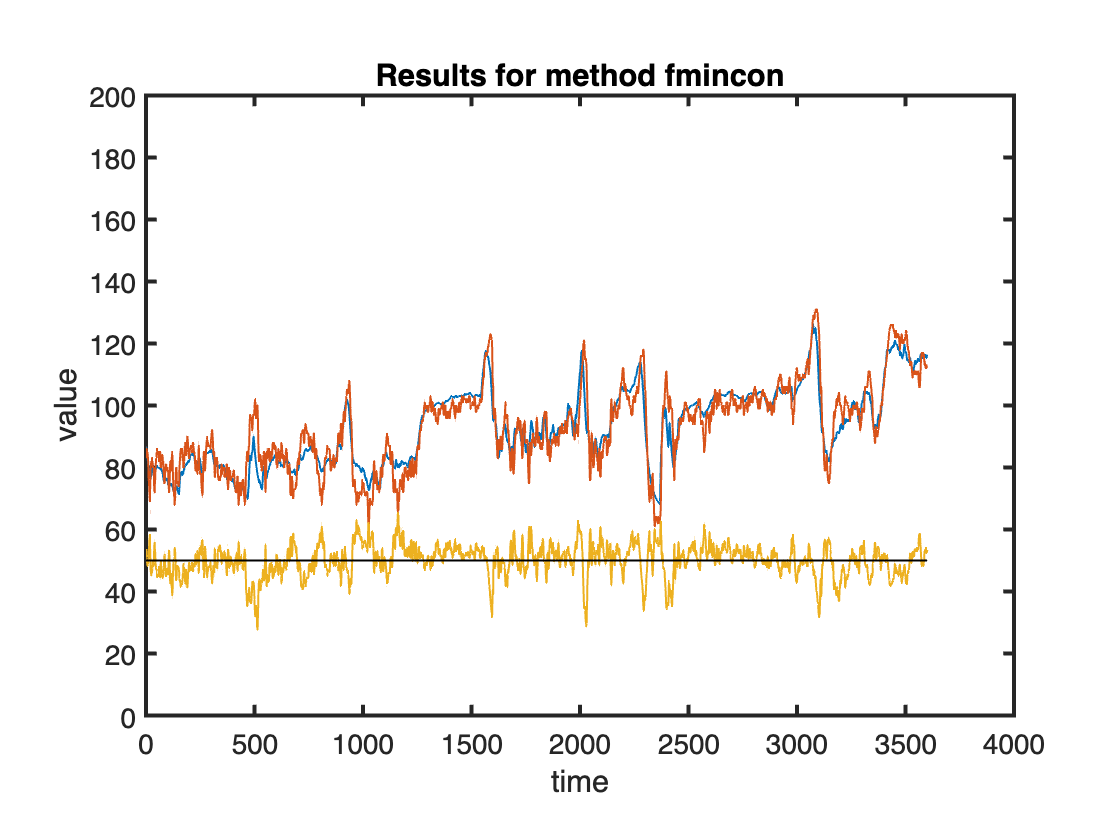

show_your_work (hr_model, hr, power, "fmincon");

function [tau, rest, gain] = ls_solve (hr, hr_prime, power)
%-----------------------------------------------------------------------
A = [-hr_prime, ones(size(power)), power];
b = hr;
tol = 1e-6;
maxiter = 10;
x = lsqr(A,b,tol,maxiter);
tau = x(1); rest = x(2); gain = x(3);  
end
%-----------------------------------------------------------------------

%-----------------------------------------------------------------------
function [tau, hr0, rest, gain] = ip_solve (hr, power)
%-----------------------------------------------------------------------
% Interior point solver fmincon from Matlab
% Initialize solution parameters
npar = 4;
x = zeros(1,npar);
tau = 23.0;  x0(1) = tau;
hr0 = 75.0; x0(2) = hr0;
rest = 64;  x0(3) = rest;
gain = 0.22; x0(4) = gain;

% settings for fmincon optimization
DisplayOption = 'iter';     % fminunc options: none, iter, notify, final, iter-detailed
nstimulioptions = optimoptions('fmincon');
options = optimoptions(@fmincon, ...
    'MaxIter',500, ...
    'MaxFunEvals', 10000, ...
    'Algorithm','interior-point',...        %interior-point, sqp
    'SpecifyObjectiveGradient',false, ...
    'CheckGradients', false, ...
    'TolFun',1e-6, ...
    'TolX',1e-6, ...
    'Display', DisplayOption);

% list of constraints
tau_min = 1.0; tau_max = 50.0;
hr0_min = 50; hr0_max = 100;
rest_min = 50; rest_max = 100;
gain_min = 0.05; gain_max = 1.0;
A = [];
b = [];
Aeq = [];
beq = [];
lb(1) = tau_min; lb(2) = hr0_min; lb(3) = rest_min; lb(4) = gain_min;
ub(1) = tau_max; ub(2) = hr0_max; ub(3) = rest_max; ub(4) = gain_max;
nonlcon = [];
%
% function to be minimized
fun = @(x)opt(x, hr, power);
%
% do the optimization
tic
[x,fval,exitflag,output] = fmincon(fun,x0,A,b,Aeq,beq,lb,ub,nonlcon,options);
tau = x(1); hr0 = x(2); rest = x(3); gain = x(4);
toc
end

function out = opt(x, hr, power)
tau = x(1); hr0 = x(2); rest = x(3); gain = x(4);
hr_model = ode_solve (power, hr0, tau, rest, gain);
out = rmse(hr_model,hr);
%fprintf("opt: tau: %7.3f hr0: %7.3f rest: %7.3f gain: %7.3f   RMSE %8.3f\n", ...
%    tau, hr0, rest, gain, out);
end
%-----------------------------------------------------------------------

%-----------------------------------------------------------------------
function x_prime = sgdiff (x, order, framelen)
% Do Savitzky-Golay filtering with derivative estimation
%-----------------------------------------------------------------------
[b,g] = sgolay(order,framelen);
dx = zeros(length(x),2);
for p = 0:1
  dx(:,p+1) = conv(x, factorial(p)/(-1)^p * g(:,p+1), 'same');
end
x_prime = dx(:,2);
end

%-----------------------------------------------------------------------
function hr = ode_solve (power, hr0, tau, rest, gain)
% Solve the ODE for all N steps (seconds)
% Assumption: Power is constant in each interval of a second
% power(k) = power in the k-th second (from t=k-1 to t=k)
% hr(k) = heart rate at the ed of the k-th second, hr(k) = HR at t=k
%-----------------------------------------------------------------------
hr = zeros(size(power));
hr(1) = ode_step (hr0, power(1), tau, rest, gain);
for i = 2:size(power,1)
    hr(i) = ode_step (hr(i-1), power(i), tau, rest, gain);
end
end
%-----------------------------------------------------------------------

%-----------------------------------------------------------------------
function hr = ode_step (hr, pow, tau, rest, gain)
% Push the ODE forward by 1 second
% Input: hr = HR initial value, pow = constant power during the second
% Output: hr = HR one second later
%-----------------------------------------------------------------------
hr_equilibrium = equilibrium (pow, rest, gain);
hr = hr_equilibrium + (exp(-1/tau)) * (hr - hr_equilibrium);
end
%-----------------------------------------------------------------------

%-----------------------------------------------------------------------
function out = equilibrium (pow, rest, gain)
% Heart rate equilibrium at given power
%-----------------------------------------------------------------------
out = rest + gain * pow;
end
%-----------------------------------------------------------------------

%-----------------------------------------------------------------------
function out = rmse (x,y)
% root-mean-square error
out = sqrt(mean((x-y).^2));
end
%-----------------------------------------------------------------------

%-----------------------------------------------------------------------
function show_your_work (hr_model, hr, power, method)
%-----------------------------------------------------------------------
figure;
x=1:3600;
factor = 1;
offset = 50;
error = factor*(hr_model-hr)+offset;
%plot(x,hr_model',x,hr',x,error',x,power','LineWidth',1)
plot(x,hr_model',x,hr',x,error','LineWidth',1); hold on
plot([0 3600],[50 50], 'k','LineWidth',1);
pbaspect([1.4 1 1]);
ax = gca;
ax.LineWidth = 2.0;
ax.FontSize = 14;
str = sprintf("Results for method %s", method);
title(str);
xlabel('time')
ylabel('value')
ylim([0 200]);
end
%-----------------------------------------------------------------------


%-----------------------------------------------------------------------
function athleticData = import_data()
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["activity_id", "heartrate", "power"];
opts.VariableTypes = ["double", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["heartrate", "power"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["heartrate", "power"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "activity_id", "ThousandsSeparator", ",");

% Import the data
relativePath = fullfile('athletic-data.csv');
athleticData = readtable(relativePath, opts);
clear opts
end
%-----------------------------------------------------------------------

%-----------------------------------------------------------------------
function testData = getTestData(mainData, aId, time)        
    testDataIndex = strcmp(mainData, aId);
    filteredData = mainData(~testDataIndex, :);
    hrData = cellfun(@str2num, regexp(filteredData.('heartrate'), '\d+', 'match'));
    powData = cellfun(@str2num, regexp(filteredData.('power'), '\d+', 'match'));
    hrData = hrData(1:time);
    powData = powData(1:time);
    testData = table(hrData',powData', 'VariableNames', {'heartrate','power'});
end
%-----------------------------------------------------------------------


% % Initialize additional parameters for the MATLAB code
% HR_0 = hr_list_all(1);
% exp_hr_new = zeros(length(power), 1);
% time_vector = 1:3600;
% options = struct('digits', 15);
% est_hr = zeros(N-1, 1);
% 
% % Set the parameter values
% tau_test = s_g2_results.tau_lsm_sg;
% k_test = -s_g2_results.k_lsm_sg;
% hr_eq_test = -s_g2_results.hreq_lsm_sg;
% 
% % Initialize the first value of est_hr
% est_hr(1) = predict_hr(p0, 1, hr0_true);
% 
% % Calculate estimated HR values
% for i = 2:N-1
%     est_hr(i) = predict_hr(power(i - 1), 1, est_hr(i - 1));
% end
% 
% % Calculate RMSE
% rmse_test = sqrt(mean((est_hr - hr).^2));
% disp(rmse_test);
% 
% % Define the predict_hr function
% function hr_t = predict_hr(pow, t, hr)
%     hr_t = (hr_eq_test + k_test * pow) + exp(-t / tau_test) * (hr - hr_eq_test - k_test * pow);
% end